## Using CWT for 2D CNN

addSubPaths();

segmented_file_dir = "../physionet.org/segmented_data/";
images_dir = "../physionet.org/cwt_images";

if ~isfolder(images_dir)
    mkdir(images_dir);
end
if ~isfolder(fullfile(images_dir,"ABP"))
    mkdir(fullfile(images_dir,"ABP"));
end
if ~isfolder(fullfile(images_dir,"PPG"))
    mkdir(fullfile(images_dir,"PPG"));
end

Fs = 125;

fileList = dir(segmented_file_dir+"*.txt"); 

allData = cell(1,length(fileList));

minLength = Inf;

for idx = 1:length(fileList)
    data = importdata(segmented_file_dir + fileList(idx).name); 
    allData{idx} = data;
    minLength = min(minLength, length(data));
end

fb = cwtfilterbank('SignalLength',minLength,'VoicesPerOctave',12, 'SamplingFrequency', Fs);

for idx = 1:length(fileList)
    data = allData{idx};
    
    cfsPPG = abs(fb.wt(data(1:minLength,3)));
    
    im = ind2rgb(im2uint8(rescale(cfsPPG)),jet(128));
  
    imFileName = strcat(fileList(idx).name(1:end-4),'_','PPG','.jpg');
    imwrite(imresize(im,[1024 1024]),fullfile(images_dir,'PPG',imFileName));
    
    cfsABP = abs(fb.wt(data(1:minLength,2)));
    
    im = ind2rgb(im2uint8(rescale(cfsABP)),jet(128));
  
    imFileName = strcat(fileList(idx).name(1:end-4),'_','ABP','.jpg');
    imwrite(imresize(im,[1024 1024]),fullfile(images_dir,'ABP',imFileName));
end


addSubPaths();

segmented_file_dir = "../physionet.org/segmented_data/";
images_dir = "../physionet.org/cwt_images";

allImages = imageDatastore(fullfile(images_dir,'PPG/'),'LabelSource', 'foldernames');

[trainImages, testImages] = splitEachLabel(allImages,0.8);

[input_tbl, output_tbl, normFactors] = MLFeatureRead(...
    '../physionet.org/inputFeatures_local.csv', '../physionet.org/outputFeatures_local.csv', ...
    'NormalisationFactors_local.mat');

Removed 0 rows from datainput features has 652 rows and 612 columns 
output features has 652 rows and 605 columns 



output = table2array(output_tbl);

bp_output = output(:, [203 404 405]);

trainSize = ceil(0.8*length(bp_output));
trainOutput = bp_output(1:trainSize, :);
testOutput = bp_output(trainSize+1:end, :);

trainInput = [];
for i = 1:length(trainImages.Files)
    trainInput = cat(4,trainInput, readimage(trainImages,i));
end

testInput = [];
for i = 1:length(testImages.Files)
    testInput = cat(4,testInput, readimage(testImages,i));
end



numOutputs = size(bp_output,2);

layers = [
    imageInputLayer([1024 1024 3])
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(numOutputs)
    regressionLayer];

miniBatchSize  = 8;
validationFrequency = floor(length(trainImages.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',1e-6, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{testInput,testOutput}, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'Verbose',false);

%     'LearnRateSchedule','piecewise', ...
%     'LearnRateDropFactor',0.1, ...
%     'LearnRateDropPeriod',20, ...


Train network

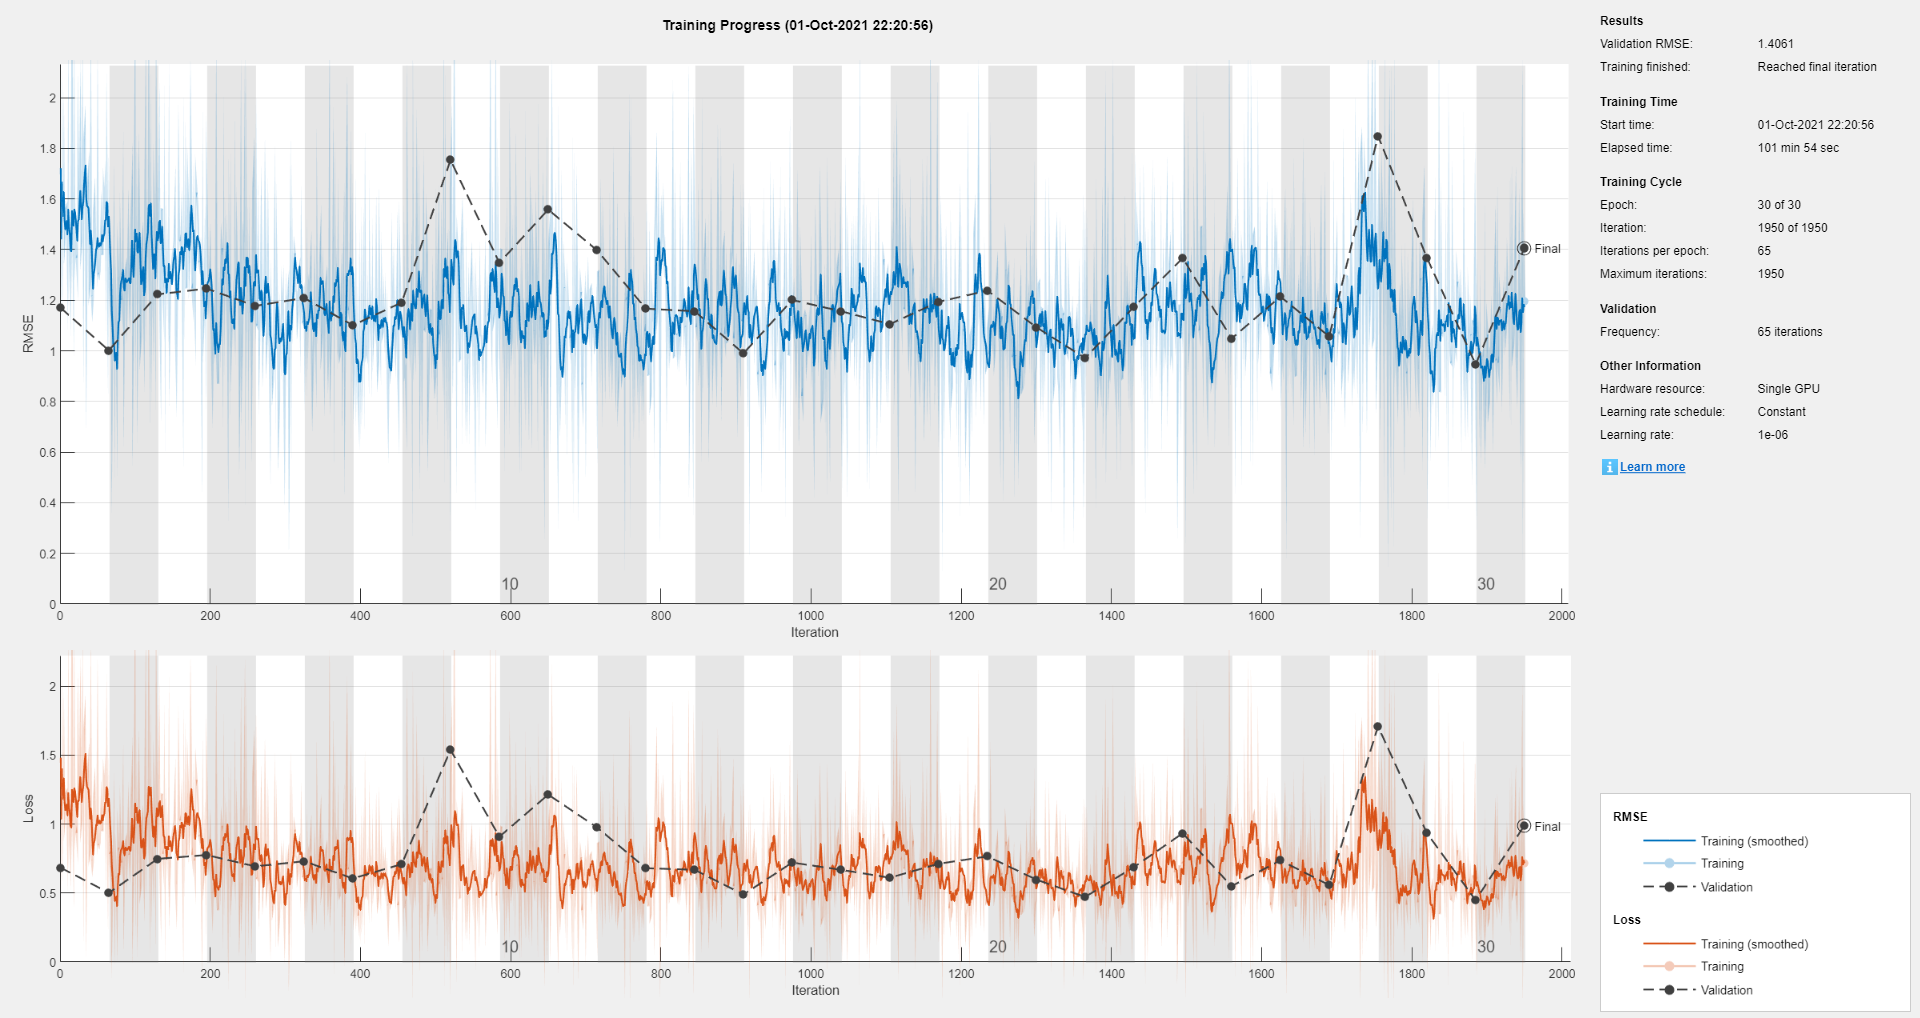

net = trainNetwork(trainInput,trainOutput,layers,options);


pred = predict(net,testInput, 'MiniBatchSize', 8);

predMAP = (pred(:,1)* normFactors('ABPAmpScale')) + normFactors('ABPAmpMean')

predMAP = 130×1 single column vector
   62.1643
   15.5706
   80.6246
   74.2686
   25.5175
    8.4109
   90.8112
  119.2907
  135.5240
   87.9693


trueMAP = (testOutput(:,1)* normFactors('ABPAmpScale')) + normFactors('ABPAmpMean')

trueMAP =    85.1763
   95.8784
   90.7620
   89.8544
   91.6948
   86.1496
   90.5707
  115.0465
  101.6968
   91.0403



predictionError =  trueMAP - predMAP;

% for MAP:
thresh = 5;
numCorrect = sum(abs(predictionError(:,1)) < thresh);
numTestSamples = length(testOutput);

accuracy = numCorrect/numTestSamples;

squares = predictionError.^2;
rmse = sqrt(mean(squares))

rmse = single
54.4153

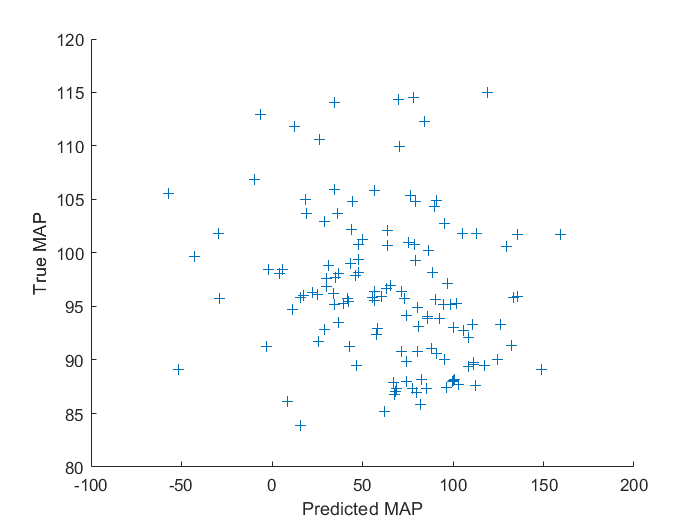


figure
scatter(predMAP,trueMAP,'+')
xlabel("Predicted MAP")
ylabel("True MAP")